% This script generates Figure 2 in the main manuscript, visualizing predictive performance across three datasets:
% (1) Discovery (3T), (2) Internal validation (7T), and (3) External validation (7T).
% Each row includes:
% - Predicted vs. true levels (group-level)
% - ROC curve (Level 1 vs Level 4 discrimination)
% - Subject-level linear fits (correlation)
% - Distribution of subject-level correlations

%% =========================
% Load data
% =========================

load('Figure_codes/Figure_data/MVPA_results.mat');


%% =======================
% Experimatental parameters
% ========================
nlevel = 4;
nrepeat = 10;
nsub_3T = 43;
nsub_7T_internal = 39;
nsub_7T_independent = 19;


%% =========================
% Visualization parameters
% =========================

param.font_size  = 12;
param.line_width = 1;
param.marker_size = 5;
param.tick_length = 0.02;

% Color definitions
param.color_map = flip([143, 158, 202;169, 195, 222;201, 218, 234; 237,245,249]/255);
param.color = [143, 158, 202]/255;



figure();
hold on;
%% =========================
% Dataset 1: Discovery (3T)
% =========================

nsub = nsub_3T;
PV = reshape(mean(out.ordered_PV,2), [nlevel, nsub])';

subplot(3,4,1)
plot_prediction_panel(PV, nlevel, param);

subplot(3,4,2)
plot_roc_panel(PV, nsub, param);

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 93% CI(85%-100%)	Spec:	 93% CI(85%-100%)	PPV:	 93% CI(85%-100%)	Nonparametric AUC:	0.98	Parametric d_a:	2.09	  Accuracy:	 93% +- 3.9% (SE), P = 0.000000



subplot(3,4,3)
[r1, rmse1] = plot_subject_fit(PV, nlevel, nsub, param);

subplot(3,4,4)
plot_violin_panel(r1, param);

%% =========================
% Dataset 2: Internal validation (7T)
% =========================

nsub = nsub_7T_internal;
PV = reshape(mean(out.ordered_PV_validation,2), [nlevel, nsub])';

subplot(3,4,5)
plot_prediction_panel(PV, nlevel, param);

subplot(3,4,6)
plot_roc_panel(PV, nsub, param);

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 85% CI(73%-95%)	Spec:	 85% CI(72%-95%)	PPV:	 85% CI(71%-95%)	Nonparametric AUC:	0.96	Parametric d_a:	1.66	  Accuracy:	 85% +- 5.8% (SE), P = 0.000014



subplot(3,4,7)
[r2, rmse2] = plot_subject_fit(PV, nlevel, nsub, param);

subplot(3,4,8)
plot_violin_panel(r2, param);


%% =========================
% Dataset 3: External validation (7T)
% =========================

nsub = nsub_7T_independent;
PV = independent_7T_output;

subplot(3,4,9)
plot_prediction_panel(PV, nlevel, param);

subplot(3,4,10)
plot_roc_panel(PV, nsub, param);

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 79% CI(60%-95%)	Spec:	 79% CI(59%-95%)	PPV:	 79% CI(60%-96%)	Nonparametric AUC:	0.76	Parametric d_a:	0.72	  Accuracy:	 79% +- 9.4% (SE), P = 0.019211


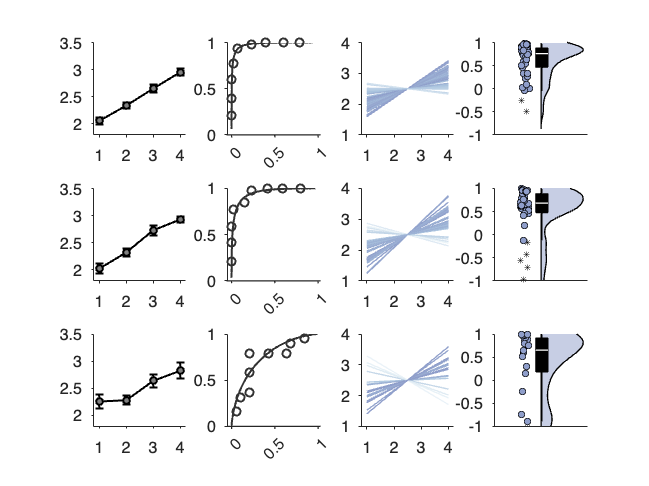


subplot(3,4,11)
[r3, rmse3] = plot_subject_fit(PV, nlevel, nsub, param);

subplot(3,4,12)
plot_violin_panel(r3, param);


%% =========================
% Helper functions
% =========================

function plot_prediction_panel(PV, nlevel,param)
    hold on;
    line_wid = param.line_width;
    mk_size = param.marker_size;
    lineplot_columns(1:nlevel, PV, ...
        'color',[0 0 0],'markerfacecolor',[.5 .5 .5], ...
        'w',1.5 * line_wid,'markersize',mk_size);

    xlim([0.8 nlevel+0.2]);
    ylim([1.8 3.5]);

    xticks(1:nlevel);
    yticks([2 2.5 3 3.5]);

    format_axis(param.font_size,line_wid,param.tick_length);
end

function plot_roc_panel(PV, nsub,param)
    line_wid = param.line_width;
    roc_plot([PV(:,end); PV(:,1)], ...
        [ones(nsub,1); zeros(nsub,1)], ...
        'twochoice','lineWidth',1.5 * line_wid);

    xlim([-0.05 1.02]);
    ylim([0 1]);

    xticks([0 0.5 1]);
    yticks([0 0.5 1]);
    xlabel([]);ylabel([]);

    format_axis(param.font_size,line_wid,param.tick_length);
end

function [r, rmse] = plot_subject_fit(PV, nlevel, nsub, param)

    hold on;

    colormap_map = param.color_map;
    line_wid = param.line_width;
    for i = 1:nsub
        x = (1:nlevel)';
        y = PV(i,:); y = y(:);

        r(i) = corr(x,y);
        rmse(i) = sqrt(mean((y-x).^2));

        p = polyfit(x,y,1);
        yfit = polyval(p,x);

        c = interp1(linspace(-1,1,size(colormap_map,1)), colormap_map, r(i));
        plot(x,yfit,'-','Color',c,'LineWidth',line_wid);
    end

    xlim([0.8 4.2]); ylim([1 4]);
    xticks([1 2 3 4]); yticks([1 2 3 4]);

    format_axis(param.font_size,line_wid,param.tick_length);
end



function plot_violin_panel(r,param)
    color = param.color;
    scatter_size = 2 * param.font_size;
    daviolinplot(r(:), ...
        'colors',color,'scattercolors','same', ...
        'scatter',2,'jitter',1,'jitterspacing',3,...
        'box',3,'scattersize',scatter_size,'boxwidth',0.8,...
        'violinalpha',0.5);


    ylim([-1 1]);yticks([-1,-0.5, 0, 0.5 1]);
    xticks([]);xlim([0.7,1.3])
    format_axis(param.font_size,param.line_width,param.tick_length);
end

function format_axis(fs, lw, tick_len, scale)
% Standard axis formatting
% scale: optional aspect ratio [x y z], default = [1 1 1]

    if nargin < 4 || isempty(scale)
        scale = [1 1 1];
    end

    set(gca, ...
        'FontSize', fs, ...
        'LineWidth', lw, ...
        'TickDir', 'out', ...
        'TickLength', [tick_len tick_len]);

    pbaspect(scale);
    box off;
end